## Problem 1:

g1taps = [3 10]; % Taps used to generate G1
g2taps = [2 3 6 8 9 10]; % Taps used to generate G2
ICs = [1 1 1 1 1 1 1 1 1 1]; % Initial conditions used to Generate both G1 and G2

% Generating both G1 and G2 using function 1
G1 = gpsgen(ICs, g1taps);
G2 = gpsgen(ICs, g2taps);

## Problem 2:

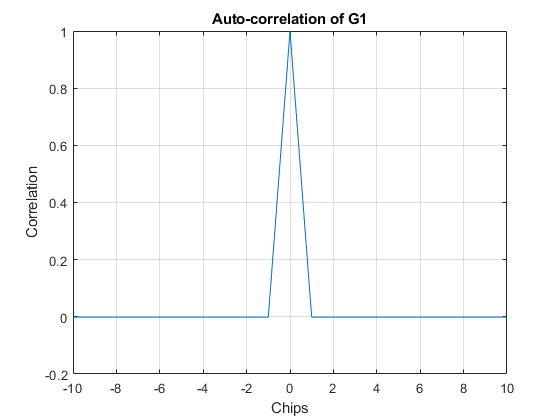

% Using function 2 to map G1 and G2: [1,0] = [-1,+1]
G1_b = bpsk(G1);
G2_b = bpsk(G2);

% Calculating the auto and cross correlations of G1 and G2
[rauto,~] = circcorr(G1_b,G1_b,1);
[rcross,t] = circcorr(G1_b,G2_b,1);

figure(1)
plot(t,rauto(:,1))
xlim([-10,10])
title('Auto-correlation of G1')
xlabel('Chips')
ylabel('Correlation')
grid on

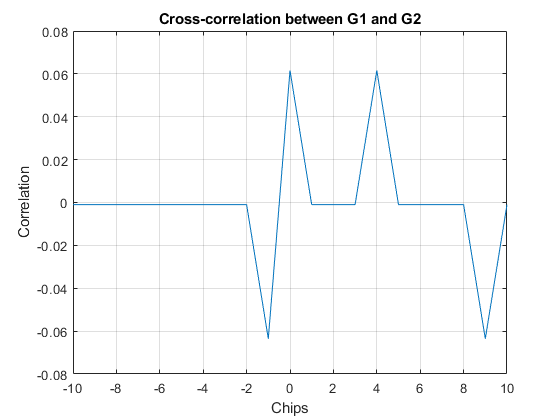

figure(2)
plot(t,rcross(:,1))
title('Cross-correlation between G1 and G2')
xlabel('Chips')
ylabel('Correlation')
xlim([-10,10])    
grid on

## Problem 3:

% PRN 14
prn14taps = [7 8]; % Taps used to generate PRN14
s_14 = cycleadd(G1(:,10),G2,prn14taps) % Using function 3 to generate PRN14

s_14 =      1
     1
     1
     1
     1
     1
     1
     0
     1
     0


s_14b = bpsk(s_14) % Binary shifting PRN14 using function 2

s_14b =     -1
    -1
    -1
    -1
    -1
    -1
    -1
     1
    -1
     1


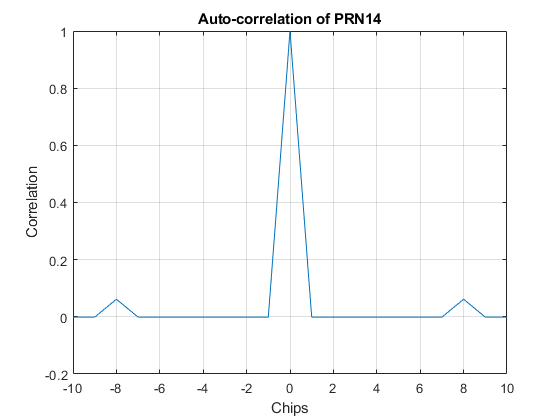


[R14auto,t] = circcorr(s_14b,s_14b,1); % Calculating auto-correlation of PRN14
figure(3)
plot(t,R14auto)
title('Auto-correlation of PRN14')
xlabel('Chips')
ylabel('Correlation')
xlim([-10,10])
grid on

prn25taps = [5 7];
s_25 = cycleadd(G1(:,10),G2,prn25taps)

s_25 =      1
     1
     1
     1
     1
     0
     0
     0
     1
     1


s_25b = bpsk(s_25)

s_25b =     -1
    -1
    -1
    -1
    -1
     1
     1
     1
    -1
    -1


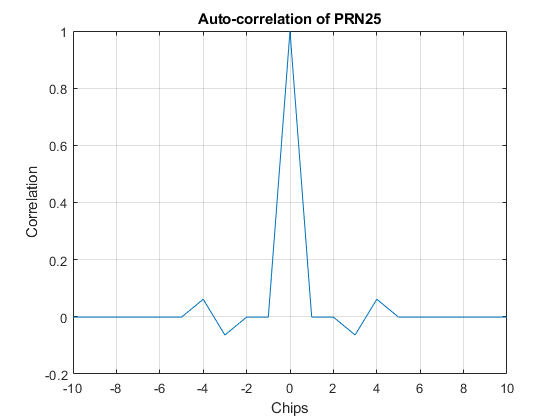

[R25auto,t] = circcorr(s_25b,s_25b,1);
figure(4)
plot(t,R25auto)
title('Auto-correlation of PRN25')

xlabel('Chips')
ylabel('Correlation')
xlim([-10,10])
grid on

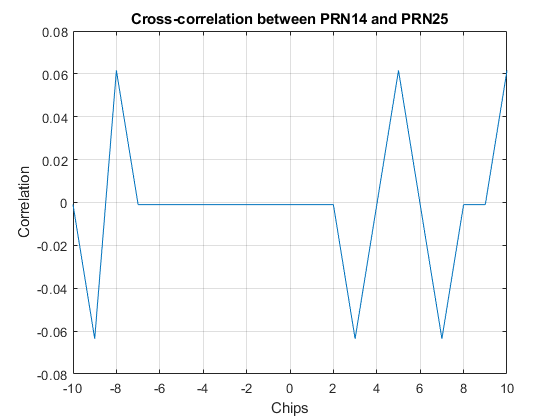

figure(5)
[R1425, t] = circcorr(s_14b,s_25b,1); % Calculating cross-correlation between PRN14 and PRN25
plot(t,R1425)
title('Cross-correlation between PRN14 and PRN25')
xlabel('Chips')
ylabel('Correlation')
xlim([-10,10])
grid on

Function 1: Generating Gold Codes

function G = gpsgen(ICs, taps)
    n = length(ICs);
    num = 2^n -1;
    G = zeros(num,n);
    G(1,:) = ICs;
    for i = 1:num-1
        temp = mod(sum(G(i,taps)),2); % mod2 add
        G(i+1,2:n) = G(i,1:n-1); % shift
        G(i+1,1) = temp; % replace first index
    end
end

Function 2: Binary Phase Shift Keying

function G_b = bpsk(G)
    G_b = G; 
    G_b(G_b == 1) = -1;
    G_b(G_b == 0) = 1; 
end

Function 3: Cycle Add Generator

function s_i = cycleadd(G1, G2, prntaps)
    G2_i = G2(:,1); % create new vector with values of G2
    for i = 1:length(G2)
        G2_i(i) = mod(sum(G2(i,prntaps)),2); % phase select values from G2 code with PRN taps
    end
    s_i = mod(G1+G2_i,2); % modulo-2 add G1 and G2 codes
end